disp('Metoda Newtona')

Metoda Newtona



% Funkcja metody Newtona
function [tableResults, errors, num_iter] = newton_method(f, x_start, delta, x_ref)
    x_curr = x_start;
    f_prime = @(x) (f(x + 1e-10) - f(x - 1e-10)) / (2 * 10^-10);
    k = 1;
    iter_data = [];

    % Warunek while: abs(x_curr - x_ref) >= delta
    while abs(x_curr - x_ref) >= delta
        x_next = x_curr - f(x_curr) / f_prime(x_curr);
        f_val = f(x_next);
        iter_data = [iter_data; k, x_next, f_val];
        
        if abs(x_next - x_ref) < delta
            break;
        end
        
        x_curr = x_next;
        k = k + 1;
    end

    tableResults = array2table(iter_data, 'VariableNames', {'Iteration', 'x', 'f(x)'});
    errors = abs(iter_data(:, 2) - x_ref); % Błąd bezwzględny względem x_ref
    num_iter = k;
end

% funkcja
f = @(x) 2 * exp(-((x/3-1).^2)).^2 + 5*sqrt(x) - 8;

x_span = [1, 10];
delta = 10^-10;

% Obliczenie miejsca zerowego za pomocą fzero jako punkt odniesienia
x_ref = fzero(f, x_span);
disp(['Miejsce zerowe obliczone za pomocą fzero: ', num2str(x_ref)]);

Miejsce zerowe obliczone za pomocą fzero: 1.7397



% Wywołanie funkcji newton_method i wyświetlenie wyników
[tableResults_newton1, errors_newton1, num_iter_newton1] = newton_method(f, x_span(1), delta, x_ref);
disp('Wyniki dla x_start = x_min');

Wyniki dla x_start = x_min


disp(tableResults_newton1);

    Iteration      x          f(x)    
    _________    ______    ___________

        1        1.6741       -0.17757
        2        1.7391     -0.0015124
        3        1.7397    -1.1931e-07
        4        1.7397     2.1316e-14




[tableResults_newton2, errors_newton2, num_iter_newton2] = newton_method(f, x_span(2), delta, x_ref);
disp('Wyniki dla x_start = x_max');

Wyniki dla x_start = x_max


disp(tableResults_newton2);

    Iteration       x          f(x)    
    _________    _______    ___________

        1        0.11789        -5.9675
        2        0.89432        -2.5249
        3         1.6498        -0.2441
        4         1.7386     -0.0028048
        5         1.7397    -4.0459e-07
        6         1.7397    -5.9064e-13



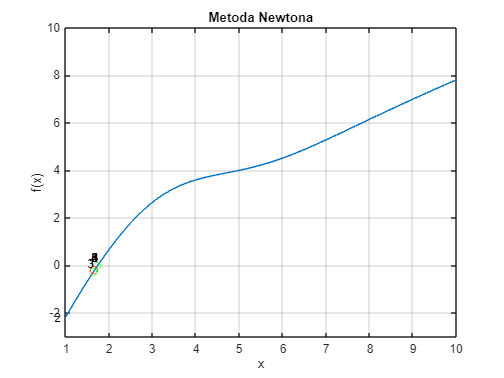


% Rysowanie wykresu metody Newtona dla obu punktów startowych
figure;
fplot(f, x_span);
xlabel('x');
ylabel('f(x)');
title('Metoda Newtona');
grid on;
axis([1 10 -3 10]); % Przeskalowanie osi
hold on;
for i = 1:height(tableResults_newton1)
    plot(tableResults_newton1.x(i), tableResults_newton1.('f(x)')(i), 'ro');
    text(tableResults_newton1.x(i), tableResults_newton1.('f(x)')(i), num2str(i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
for i = 1:height(tableResults_newton2)
    plot(tableResults_newton2.x(i), tableResults_newton2.('f(x)')(i), 'go');
    text(tableResults_newton2.x(i), tableResults_newton2.('f(x)')(i), num2str(i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;

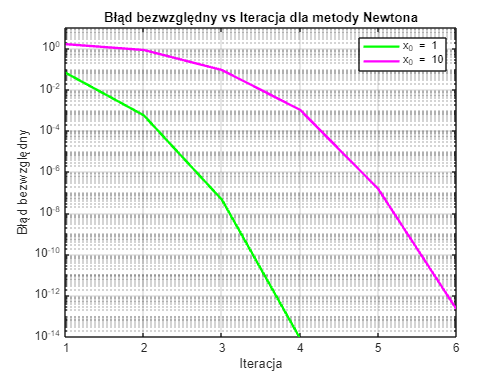


% Rysowanie wykresu błędów bezwzględnych dla metody Newtona dla obu punktów startowych
figure;
semilogy(1:length(errors_newton1), errors_newton1, 'g-', 'LineWidth', 2);
hold on;
semilogy(1:length(errors_newton2), errors_newton2, 'm-', 'LineWidth', 2);
xlabel('Iteracja');
ylabel('Błąd bezwzględny');
title('Błąd bezwzględny vs Iteracja dla metody Newtona');
legend('x_0 = 1', 'x_0 = 10');
grid on;
xlim([1, max(length(errors_newton1), length(errors_newton2))]); % Ustawienie zakresu osi X
ylim([10^-14, 10]); % Ustawienie zakresu osi Y
hold off;


% Zakres wartości delta
deltas = logspace(-15, -1, 15);

% Wyznaczenie liczby iteracji dla różnych wartości delta
num_iterations_newton_start1 = zeros(length(deltas), 1);
num_iterations_newton_start2 = zeros(length(deltas), 1);
for j = 1:length(deltas)
    epsilon = deltas(j);
    [~, ~, num_iter1] = newton_method(f, x_span(1), epsilon, x_ref);
    num_iterations_newton_start1(j) = num_iter1;
    [~, ~, num_iter2] = newton_method(f, x_span(2), epsilon, x_ref);
    num_iterations_newton_start2(j) = num_iter2;
end

% Wyświetlenie wyników w tabeli
iterations_table_newton = table(deltas', num_iterations_newton_start1, num_iterations_newton_start2, 'VariableNames', {'Delta', 'Newton x_0 = 1', 'Newton x_0 = 10'});
disp(iterations_table_newton);

    Delta     Newton x_0 = 1    Newton x_0 = 10
    ______    ______________    _______________

     1e-15          5                  7       
     1e-14          4                  7       
     1e-13          4                  7       
     1e-12          4                  6       
     1e-11          4                  6       
     1e-10          4                  6       
     1e-09          4                  6       
     1e-08          4                  6       
     1e-07          3                  6       
     1e-06          3                  5       
     1e-05          3                  5       
    0.0001          3                  5       
     0.001          2                  5       
      0.01          2                  4       
       0.1          1                  3       



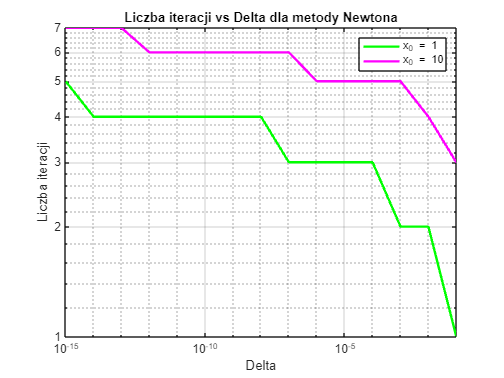


% Rysowanie wykresu liczby iteracji w zależności od delta dla metody Newtona
figure;
loglog(deltas, num_iterations_newton_start1, 'g-', 'LineWidth', 2);
hold on;
loglog(deltas, num_iterations_newton_start2, 'm-', 'LineWidth', 2);
xlabel('Delta');
ylabel('Liczba iteracji');
title('Liczba iteracji vs Delta dla metody Newtona');
legend('x_0 = 1', 'x_0 = 10');
grid on;
axis tight; % Automatyczne dopasowanie osi
hold off;